# **CA#3**

## **Sogol Goodarzi**

## **810198467**

# ** Part 1. Transmitter**

## *** Phase Modulation * **

## 1.3)

### Plotting the Modulated Signals

### 
$$\varphi_{\Delta } =10$$


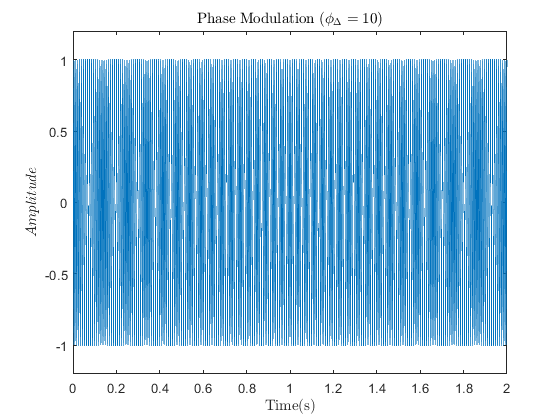

clear
fs=10000;
t=0:1/fs:10;
Ac=1;
fc=100;
phi_delta=10;
m=sin(pi*t);
xc_pm=pm(m,t,Ac,fc,phi_delta);
xc_nbpm=nbpm(m,t,Ac,fc,phi_delta);
plot(t,xc_pm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Phase Modulation $(\phi_\Delta=10)$','Interpreter','latex')

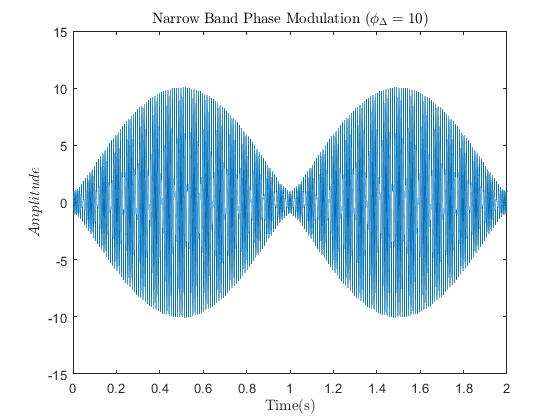

plot(t,xc_nbpm);
xlim([0 2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Narrow Band Phase Modulation $(\phi_\Delta=10)$','Interpreter','latex')

### Mean-Squared Error of pm and nbpm output signals

Error=immse(xc_pm,xc_nbpm);
fprintf('The mean-squared error is %0.5f', Error);

The mean-squared error is 25.81095

## 1.4)

### Plotting the Modulated Signals

### 
$$\varphi_{\Delta } =0\ldotp 01$$


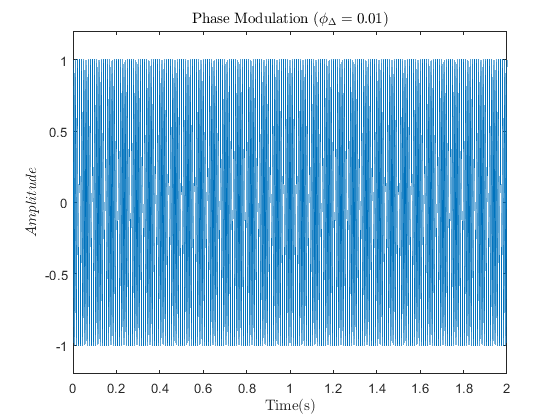

phi_delta=0.01;
xc_pm=pm(m,t,Ac,fc,phi_delta);
xc_nbpm=nbpm(m,t,Ac,fc,phi_delta);
plot(t,xc_pm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Phase Modulation $(\phi_\Delta=0.01)$','Interpreter','latex')

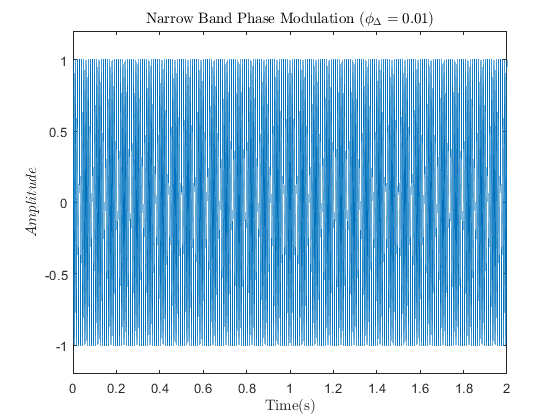

plot(t,xc_nbpm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Narrow Band Phase Modulation $(\phi_\Delta=0.01)$','Interpreter','latex')

### Mean-Squared Error of pm and nbpm output signals

Error=immse(xc_pm,xc_nbpm);
fprintf('The mean-squared error is %0.12f', Error);

The mean-squared error is 0.000000000469

## 1.5) 

### Plotting outputs with pmmod()

### 
$$\varphi_{\Delta } =10$$


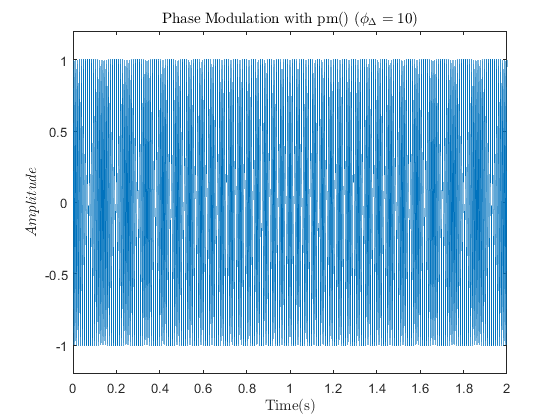

phi_delta=10;
xc_pm=pm(m,t,Ac,fc,phi_delta);
xc_pmmod=pmmod(m,fc,fs,phi_delta);
plot(t,xc_pm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Phase Modulation with pm() $(\phi_\Delta=10)$','Interpreter','latex')

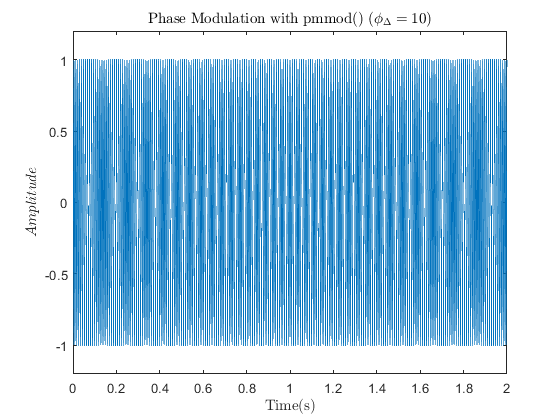

plot(t,xc_pmmod);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Phase Modulation with pmmod() $(\phi_\Delta=10)$','Interpreter','latex')

### 
$$\varphi_{\Delta } =0\ldotp 01$$


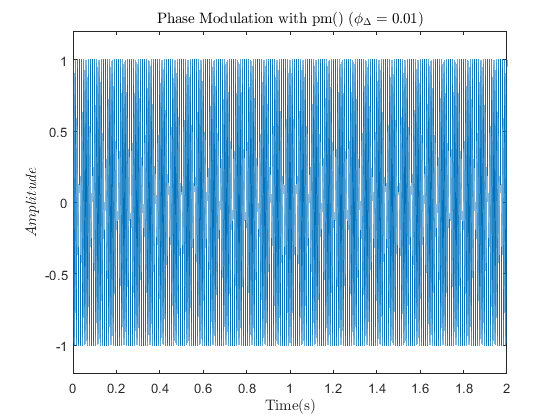

phi_delta=0.01;
xc_pm=pm(m,t,Ac,fc,phi_delta);
xc_pmmod=pmmod(m,fc,fs,phi_delta);
plot(t,xc_pm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Phase Modulation with pm() $(\phi_\Delta=0.01)$','Interpreter','latex')

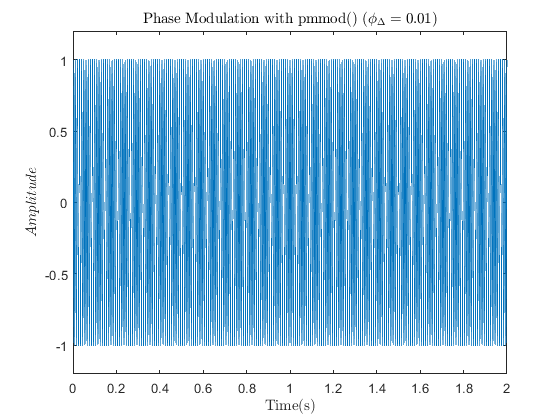

plot(t,xc_pmmod);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Phase Modulation with pmmod() $(\phi_\Delta=0.01)$','Interpreter','latex')

## 1.6) 

### Mean-Squared Error of pm() and pmmod() outputs for $\varphi_{\Delta } =10$

phi_delta=10;
xc_pm=pm(m,t,Ac,fc,phi_delta);
xc_pmmod=pmmod(m,fc,fs,phi_delta);
Error=immse(xc_pm,xc_pmmod);
fprintf('The mean-squared error of pm() and pmmod() %0.15f', Error);

The mean-squared error of pm() and pmmod() 0.000000000000000

## *** Frequency Modulation ***

## 1.8)

### Plotting the Modulated Signals

### 
$$f_{\Delta } =10$$


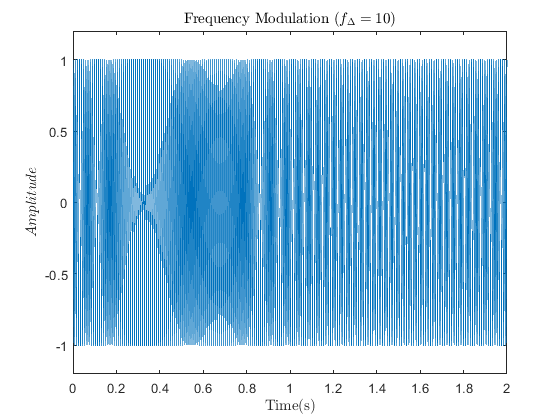

clear
fs=10000;
t=0:1/fs:10;
Ac=1;
fc=100;
f_delta=10;
m=sin(pi*t);
xc_fm=fm(m,t,Ac,fc,f_delta);
xc_nbfm=nbfm(m,t,Ac,fc,f_delta);
plot(t,xc_fm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Frequency Modulation $(f_\Delta=10)$','Interpreter','latex')

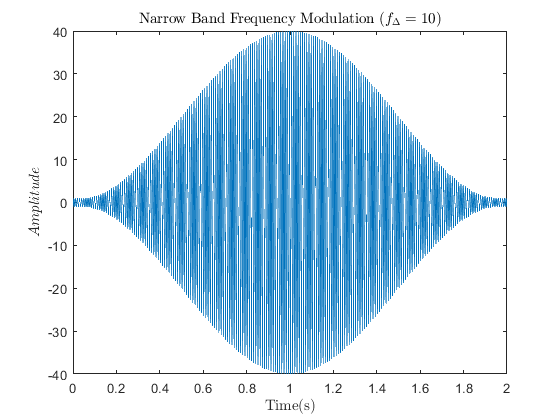

plot(t,xc_nbfm);
xlim([0 2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Narrow Band Frequency Modulation $(f_\Delta=10)$','Interpreter','latex')

### Mean-Squared Error of fm and nbfm output signals

Error=immse(xc_fm,xc_nbfm);
fprintf('The mean-squared error is %0.12f', Error);

The mean-squared error is 297.333706537754

## 1.9)

### Plotting the Modulated Signals

### 
$$f_{\Delta } =0\ldotp 01$$


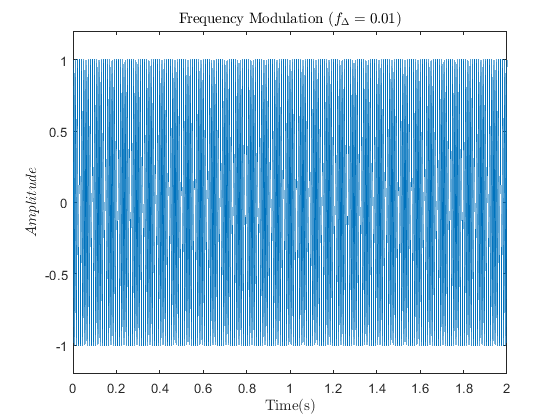

f_delta=0.01;
xc_fm=fm(m,t,Ac,fc,f_delta);
xc_nbfm=nbfm(m,t,Ac,fc,f_delta);
plot(t,xc_fm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Frequency Modulation $(f_\Delta=0.01)$','Interpreter','latex')

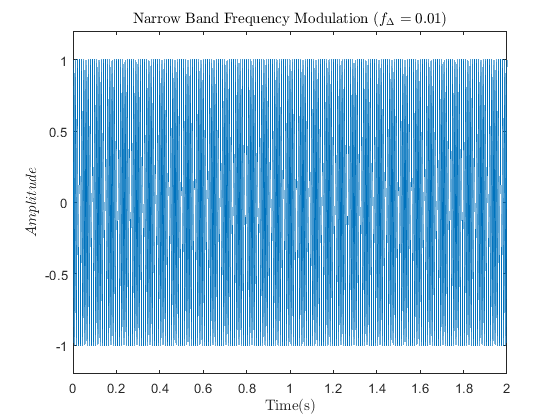

plot(t,xc_nbfm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Narrow Band Frequency Modulation $(f_\Delta=0.01)$','Interpreter','latex')

### Mean-Squared Error of fm and nbfm output signals

Error=immse(xc_fm,xc_nbfm);
fprintf('The mean-squared error is %0.12f', Error);

The mean-squared error is 0.000000087493

## 1.10)

### Plotting outputs with fmmod()

### 
$$f_{\Delta } =10$$


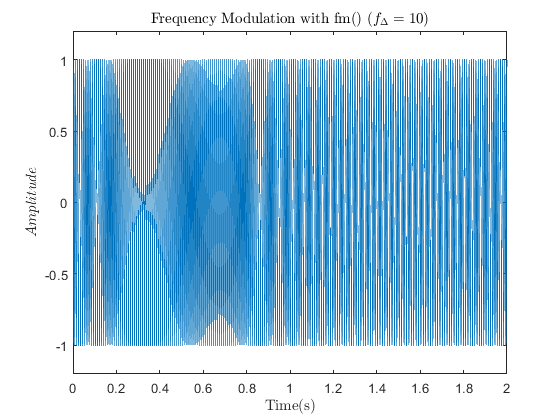

f_delta=10;
xc_fm=fm(m,t,Ac,fc,f_delta);
xc_fmmod=fmmod(m,fc,fs,f_delta);
plot(t,xc_fm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Frequency Modulation with fm() $(f_\Delta=10)$','Interpreter','latex')

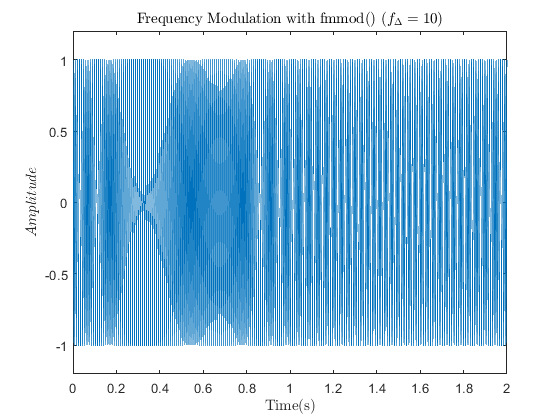

plot(t,xc_fmmod);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Frequency Modulation with fmmod() $(f_\Delta=10)$','Interpreter','latex')

### 
$$f_{\Delta } =0\ldotp 01$$


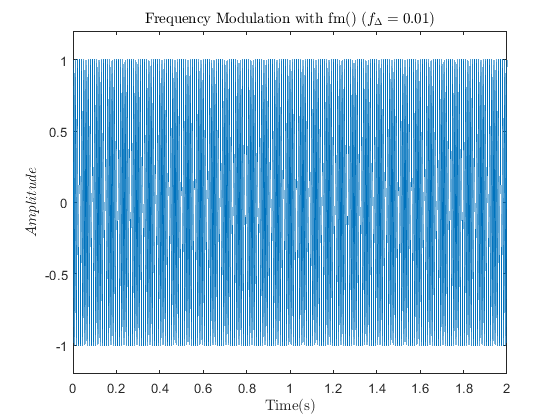

f_delta=0.01;
xc_fm=fm(m,t,Ac,fc,f_delta);
xc_fmmod=fmmod(m,fc,fs,f_delta);
plot(t,xc_fm);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Frequency Modulation with fm() $(f_\Delta=0.01)$','Interpreter','latex')

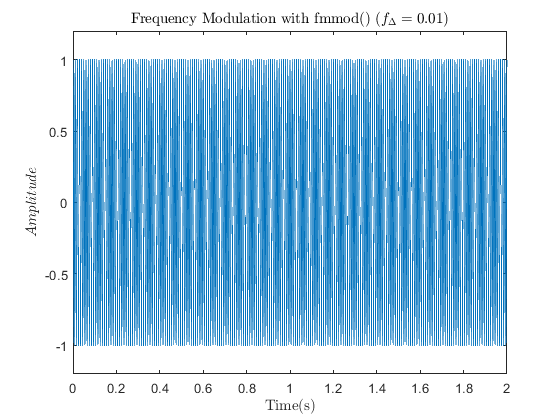

plot(t,xc_fmmod);
xlim([0 2]);
ylim([-1.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Frequency Modulation with fmmod() $(f_\Delta=0.01)$','Interpreter','latex')

## 1.11)

### Mean-Squared Error of fm() and fmmod() outputs for $f_{\Delta } =10$

f_delta=10;
xc_fm=fm(m,t,Ac,fc,f_delta);
xc_fmmod=fmmod(m,fc,fs,f_delta);
Error=immse(xc_fm,xc_fmmod);
fprintf('The mean-squared error of fm() and fmmod() %0.7f', Error);

The mean-squared error of fm() and fmmod() 0.0000025

## 1.12)

### Mean_Squared Error for PM modulation 

### 
$$0\le \varphi_{\Delta } \le 1$$


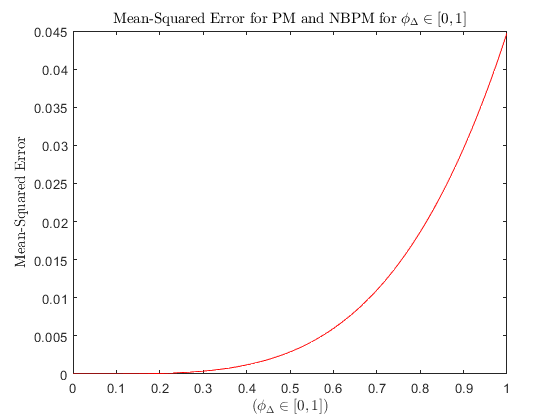

for phi_delta=0:0.01:1
    xc_pm=pm(m,t,Ac,fc,phi_delta);
    xc_nbpm=nbpm(m,t,Ac,fc,phi_delta);
    Error(int16(phi_delta*100+1))=immse(xc_pm,xc_nbpm);
end
phi_delta=0:0.01:1;
plot(phi_delta,Error,'r');
xlabel ('$(\phi_\Delta\in[0,1])$','Interpreter','latex')
ylabel ('Mean-Squared Error','Interpreter','latex')
title ('Mean-Squared Error for PM and NBPM for $\phi_\Delta\in[0,1]$','Interpreter','latex')

phi_delta_max=phi_delta(max(find(Error<0.01)));
fprintf('Maximum value for phi_delta %0.4f', phi_delta_max);

Maximum value for phi_delta 0.6800

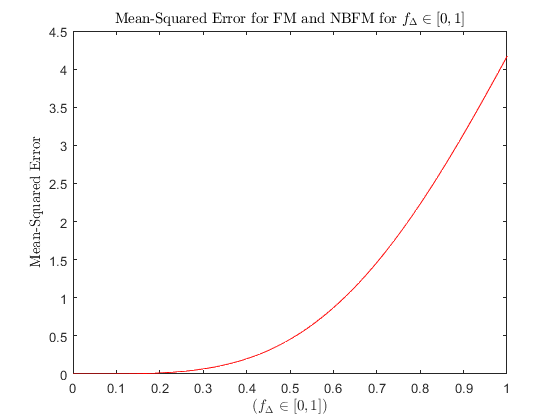

for f_delta=0:0.01:1
    xc_fm=fm(m,t,Ac,fc,f_delta);
    xc_nbfm=nbfm(m,t,Ac,fc,f_delta);
    Error(int16(f_delta*100+1))=immse(xc_fm,xc_nbfm);
end
f_delta=0:0.01:1;
plot(f_delta,Error,'r');
xlabel ('$(f_\Delta\in[0,1])$','Interpreter','latex')
ylabel ('Mean-Squared Error','Interpreter','latex')
title ('Mean-Squared Error for FM and NBFM for $f_\Delta\in[0,1]$','Interpreter','latex')

f_delta_max=f_delta(max(find(Error<0.01)));
fprintf('Maximum value for f_delta %0.4f', f_delta_max);

Maximum value for f_delta 0.1800

# **Part 2. Receiver **

## *** Frequency Modulation ***

## **2.3) Demodulation with fdm()**

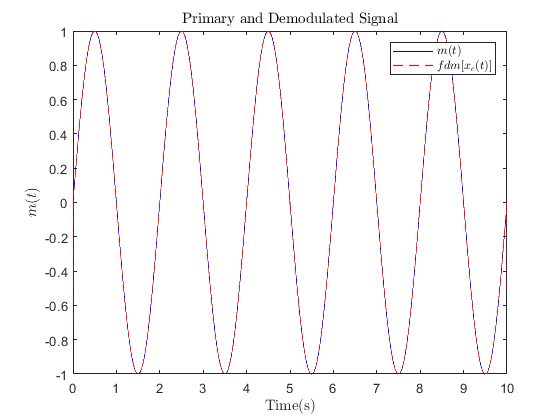

clear
fs=10000;
t=0:1/fs:10;
Ac=1;
fc=100;
f_delta=10;
m=sin(pi*t);
plot(t,m,'b');
xc_fm=fm(m,t,Ac,fc,f_delta);
m_fdm=fdm(xc_fm,Ac,fc,f_delta,fs);
hold on
plot(t,m_fdm,'r--');
ylim([-1 1]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Primary and Demodulated Signal','Interpreter','latex')
hold off
legend('$m(t)$','$fdm[x_c(t)]$','Interpreter','latex');

## 2.4) Demodulation with fmdemod()

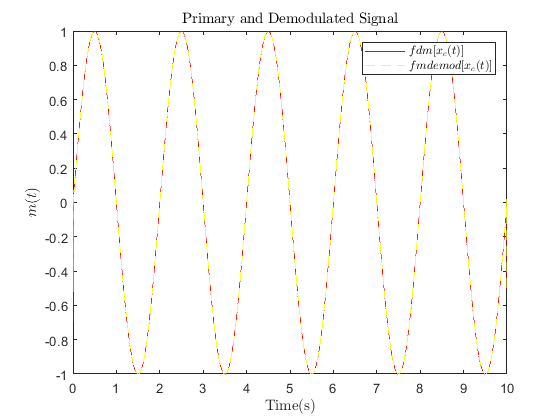

plot(t,m_fdm,'r');
hold on
m_fmdemod=fmdemod(xc_fm,fc,fs,f_delta);
plot(t,m_fmdemod,'y--');
ylim([-1 1]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Primary and Demodulated Signal','Interpreter','latex')
hold off
legend('$fdm[x_c(t)]$','$fmdemod[x_c(t)]$','Interpreter','latex');

## * Phase Modulation *

## 2.7) **Demodulation with pdm()**

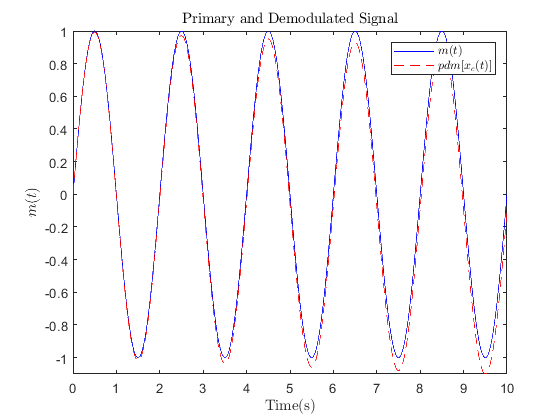

fs=10000;
t=0:1/fs:10;
Ac=1;
fc=100;
phi_delta=10;
m=sin(pi*t);
plot(t,m,'b');
hold on
xc_pm=pm(m,t,Ac,fc,phi_delta);
m_pdm=pdm(xc_pm,Ac,fc,phi_delta,fs,t);
plot(t,m_pdm,'r--');
ylim([-1.1 1]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Primary and Demodulated Signal','Interpreter','latex')
hold off
legend('$m(t)$','$pdm[x_c(t)]$','Interpreter','latex');

## 2.8) Demodulation with pmdemod()

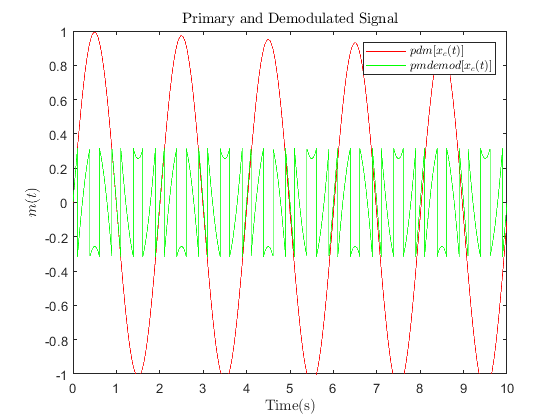

plot(t,m_pdm,'r');
hold on
m_pmdemod=pmdemod(xc_pm,fc,fs,phi_delta);
plot(t,m_pmdemod,'g');
ylim([-1 1]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Primary and Demodulated Signal','Interpreter','latex')
hold off
legend('$pdm[x_c(t)]$','$pmdemod[x_c(t)]$','Interpreter','latex');

# **Part 3. Tone Modulation **

## **3.1) Modulation with pm() function**

clear
fs=10000;
t=0:1/fs:2;
Ac=1;
fc=100;
wm=20*pi;
m=sin(wm*t);

### 
$$\beta =0\ldotp 1$$


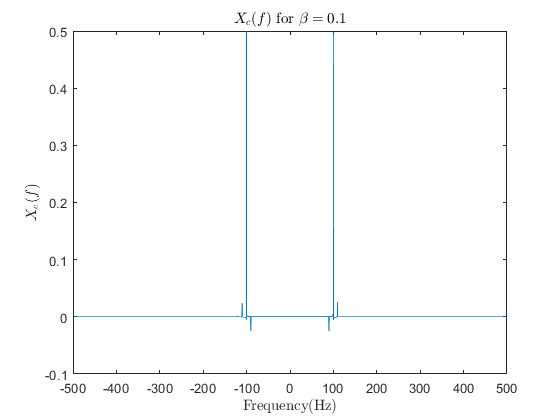

Beta=0.1;
xc=pm(m,t,Ac,fc,Beta);
N=length(xc);
f=-fs/2:fs/N:fs/2-fs/N;
FT_xc=fftshift(fft(xc));
plot(f,real(FT_xc/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=0.1$','Interpreter','latex')

### 
$$\beta =1$$


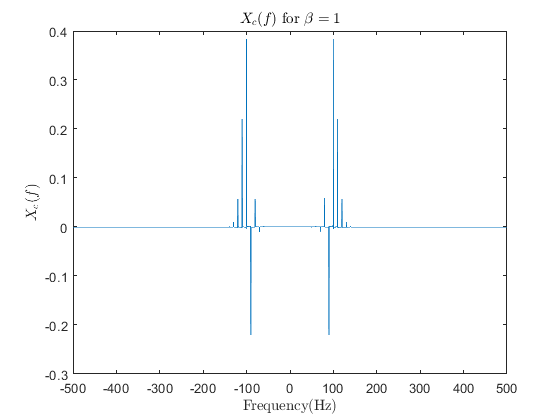

Beta=1;
xc=pm(m,t,Ac,fc,Beta);
N=length(xc);
f=-fs/2:fs/N:fs/2-fs/N;
FT_xc=fftshift(fft(xc));
plot(f,real(FT_xc/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=1$','Interpreter','latex')

### 
$$\beta =10$$


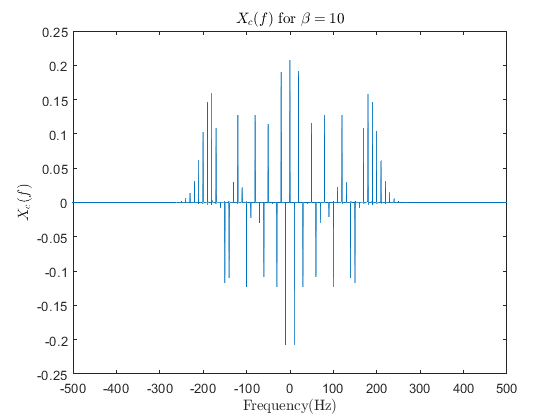

Beta=10;
xc=pm(m,t,Ac,fc,Beta);
N=length(xc);
f=-fs/2:fs/N:fs/2-fs/N;
FT_xc=fftshift(fft(xc));
plot(f,real(FT_xc/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=10$','Interpreter','latex')

## 3.2) Modulation with Bessel Function

### 
$$\beta =0\ldotp 1$$


### Finding appropriate n :

f_m=10;
n=0:10;
Beta=0.1;
Jn=besselj(n,Beta)

Jn =     0.9975    0.0499    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


### 
$$n=1$$


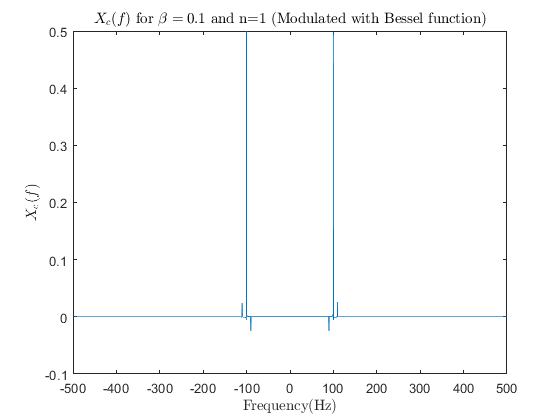

n=-1:1;
xc_bessel=zeros(1,length(t));
for i=1:length(n)
    xc_bessel=xc_bessel+Ac*besselj(n(i),Beta)*cos(2*pi*(fc+n(i)*f_m)*t);
end
FT_xc_bessel=fftshift(fft(xc_bessel));
plot(f,real(FT_xc_bessel/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=0.1$ and n=1 (Modulated with Bessel function)','Interpreter','latex')

### 
$$n=2$$


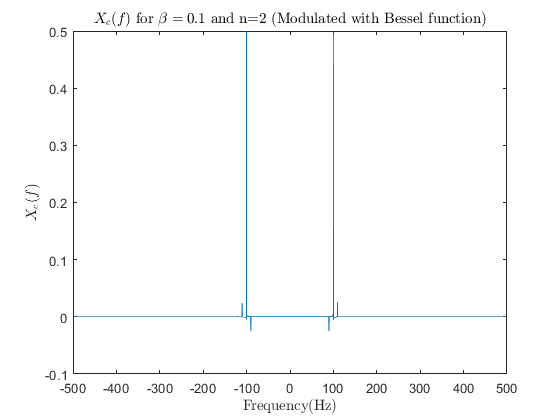

n=-2:2;
Beta=0.1;
xc_bessel=zeros(1,length(t));
for i=1:length(n)
    xc_bessel=xc_bessel+Ac*besselj(n(i),Beta)*cos(2*pi*(fc+n(i)*f_m)*t);
end
FT_xc_bessel=fftshift(fft(xc_bessel));
plot(f,real(FT_xc_bessel/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=0.1$  and n=2 (Modulated with Bessel function)','Interpreter','latex')

### Compareing both methodes 

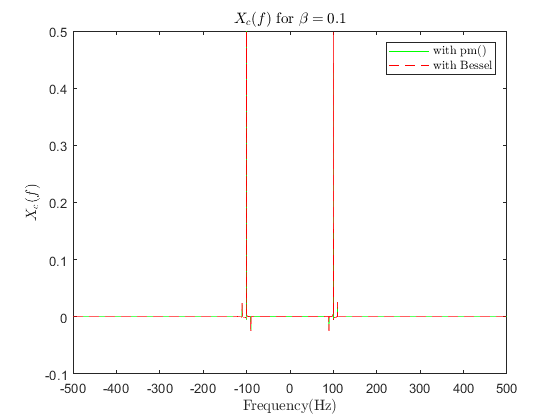

xc=pm(m,t,Ac,fc,Beta);
FT_xc=fftshift(fft(xc));
plot(f,real(FT_xc/N),'g');
hold on
plot(f,real(FT_xc_bessel/N),'r--');
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=0.1$','Interpreter','latex')
hold off
legend('with pm()','with Bessel','Interpreter','latex');

### 
$$\beta =1$$


### Finding appropriate n :

n=0:10;
Beta=1;
Jn=besselj(n,Beta)

Jn =     0.7652    0.4401    0.1149    0.0196    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000


### 
$$n=4$$


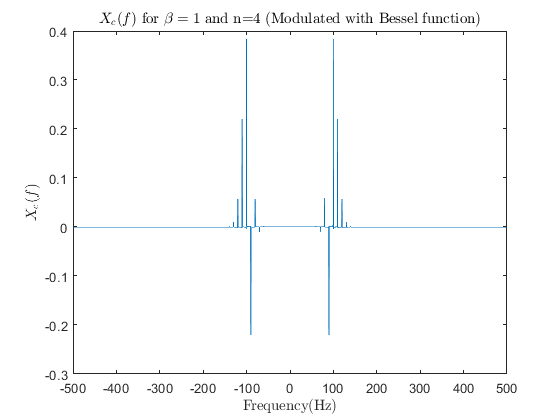

n=-4:4;
xc_bessel=zeros(1,length(t));
for i=1:length(n)
    xc_bessel=xc_bessel+Ac*besselj(n(i),Beta)*cos(2*pi*(fc+n(i)*f_m)*t);
end
FT_xc_bessel=fftshift(fft(xc_bessel));
plot(f,real(FT_xc_bessel/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=1$ and n=4 (Modulated with Bessel function)','Interpreter','latex')

### 
$$n=5$$


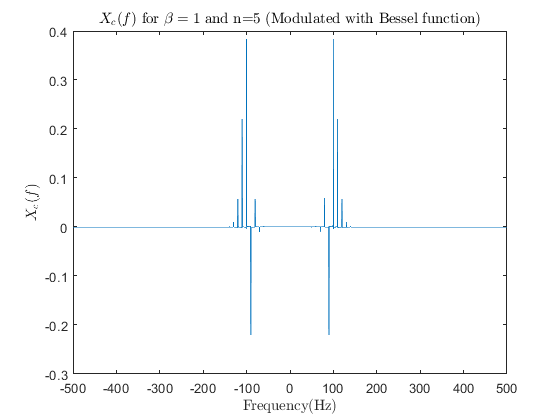

n=-5:5;
Beta=1;
xc_bessel=zeros(1,length(t));
for i=1:length(n)
    xc_bessel=xc_bessel+Ac*besselj(n(i),Beta)*cos(2*pi*(fc+n(i)*f_m)*t);
end
FT_xc_bessel=fftshift(fft(xc_bessel));
plot(f,real(FT_xc_bessel/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=1$  and n=5 (Modulated with Bessel function)','Interpreter','latex')

### Compareing both methodes 

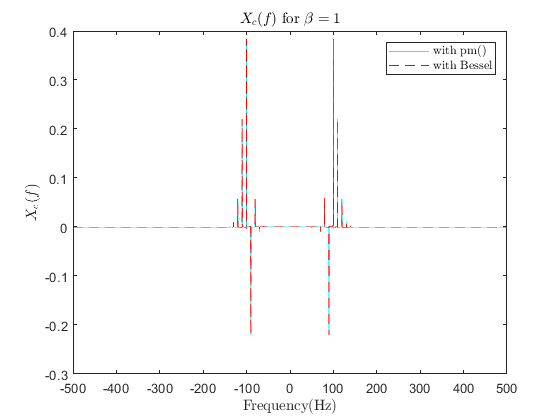

xc=pm(m,t,Ac,fc,Beta);
FT_xc=fftshift(fft(xc));
plot(f,real(FT_xc/N),'c');
hold on
plot(f,real(FT_xc_bessel/N),'r--');
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=1$','Interpreter','latex')
hold off
legend('with pm()','with Bessel','Interpreter','latex');

### 
$$\beta =10$$


### Finding appropriate n :

n=0:30;
Beta=10;
Jn=besselj(n,Beta)

Jn =    -0.2459    0.0435    0.2546    0.0584   -0.2196   -0.2341   -0.0145    0.2167    0.3179    0.2919    0.2075    0.1231    0.0634    0.0290    0.0120    0.0045    0.0016    0.0005    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


### 
$$n=12$$


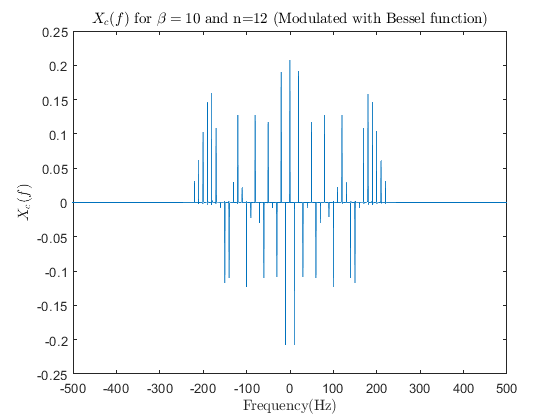

n=-12:12;
xc_bessel=zeros(1,length(t));
for i=1:length(n)
    xc_bessel=xc_bessel+Ac*besselj(n(i),Beta)*cos(2*pi*(fc+n(i)*f_m)*t);
end
FT_xc_bessel=fftshift(fft(xc_bessel));
plot(f,real(FT_xc_bessel/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=10$ and n=12 (Modulated with Bessel function)','Interpreter','latex')

### 
$$n=15$$


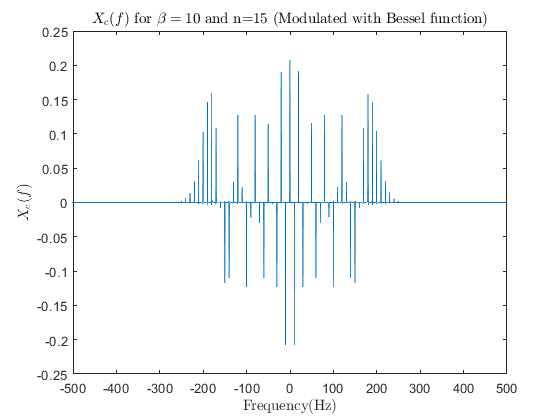

n=-15:15;
Beta=10;
xc_bessel=zeros(1,length(t));
for i=1:length(n)
    xc_bessel=xc_bessel+Ac*besselj(n(i),Beta)*cos(2*pi*(fc+n(i)*f_m)*t);
end
FT_xc_bessel=fftshift(fft(xc_bessel));
plot(f,real(FT_xc_bessel/N));
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=10$  and n=15 (Modulated with Bessel function)','Interpreter','latex')

### Compareing both methodes 

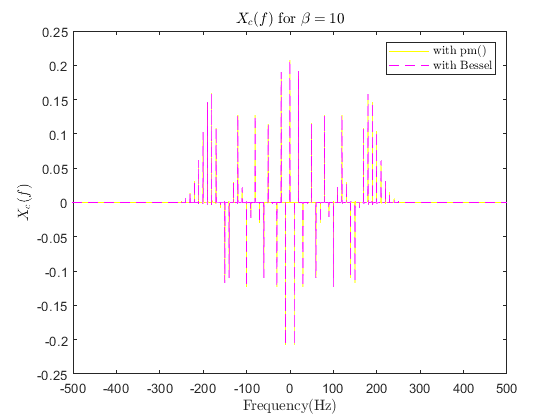

xc=pm(m,t,Ac,fc,Beta);
FT_xc=fftshift(fft(xc));
plot(f,real(FT_xc/N),'y');
hold on
plot(f,real(FT_xc_bessel/N),'m--');
xlim([-500 500])
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('$X_c(f)$ for $\beta=10$','Interpreter','latex')
hold off
legend('with pm()','with Bessel','Interpreter','latex');

# **Functions**

## **1.1) pm()**

function [xc] = pm(x,t,Ac,fc,phi_delta)
    xc=Ac*cos(2*pi*fc*t+phi_delta*x);
end

## 1.2) nbpm()

function [xc] = nbpm(x,t,Ac,fc,phi_delta)
    xc=Ac*cos(2*pi*fc*t)-Ac*phi_delta*x.*sin(2*pi*fc*t);
end

## 1.7) fm()

function [xc] = fm(x,t,Ac,fc,f_delta)
    s=cumtrapz(t,x);
    xc=pm(s,t,Ac,fc,2*pi*f_delta);
end

## nbfm()

function [xc] = nbfm(x,t,Ac,fc,f_delta)
    s=cumtrapz(t,x);
    xc=nbpm(s,t,Ac,fc,2*pi*f_delta);
end

## 2.2) fdm()

function [x] = fdm(xc,Ac,fc,f_delta,fs)
    h=1/fs;
    shifted_xc=[xc(1) xc(1:length(xc)-1)];
    dxc=(xc-shifted_xc)/h;
    [yupper,ylower]=envelope(dxc);
    yupper=yupper-Ac*2*pi*fc;
    k=Ac*2*pi*f_delta;
    x=yupper/k;
end

## 2.6) pdm()

function [x] = pdm(xc,Ac,fc,phi_delta,fs,t)
    dm=fdm(xc,Ac,fc,phi_delta/(2*pi),fs);
    x=cumtrapz(t,dm);
end